
close all
clear all
colors=npg(10); % Ten basic colors 
tpi = 2*pi;
gamma171 = 7.5e6;   % freq, Hz/T

maindir='\\Artemis-pc\Data\2026-04-20\Abs-218\';   % 对比度
load([maindir,'\FitResult.mat']);

maindir='\\Artemis-pc\Data\2026-04-20\Abs-\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat']);



% ！！注意修改 周期数 和 进动时间 ！！ %

tau_s = 6;   % s，不包含旋转位移台时间
tau_ms = 28.8;   % ms
coefficient171 = 1;

R_list = [1 -1 -1 1 -1 1 1 -1];   % 旋转序列，靠近(1)，远离(-1)

a171 = amp;   % 171 对比度
a171_sigma = a_sigma;
T171 = T;

% 进动时间，秒数在第一段修改 %
precession = tau_s*1e3 + tau_ms;   % 时序可设置的进动时间

tau171 = precession+4+4+100;
N171 = floor(tau171/T171);

% 不考虑进动曲线 Offset 
%
dphase171 = real(asin(((s1-s2)./(s1+s2))/a171));
phase171 = N171*tpi + coefficient171*dphase171;


## 差分相位


Rlen = length(R_list);
diff_n = floor(length(phase171)/Rlen);
for k = 1:diff_n
    temp = phase171((k-1)*Rlen+1:k*Rlen);
    diff_p(k) = (R_list*temp)/(Rlen/2);
end
diff_f = diff_p/(tau171*1e-3)/tpi;   % Hz
diff_B = diff_f/gamma171*1e9;   % nT

pm = mean(diff_p);
fm = mean(diff_f);
Bm = mean(diff_B);

pstd = std(diff_p)/sqrt(diff_n-1);
fstd = std(diff_f)/sqrt(diff_n-1);
Bstd = std(diff_B)/sqrt(diff_n-1);


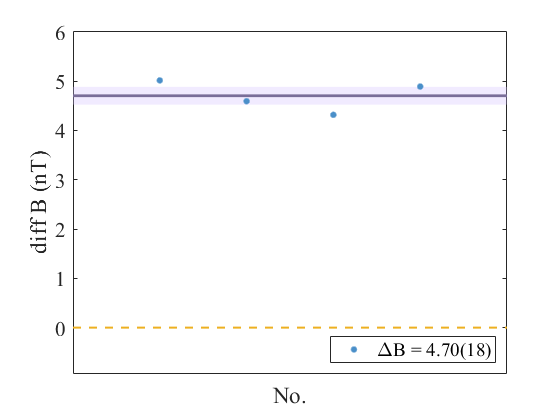


f1 = figure; hold on;

xmin = 0;
xman = diff_n+1;
ymin = min([-abs(pm*0.2) min(diff_p)*0.8 min(diff_p)*1.2]);
ymax = max([abs(pm*0.2) max(diff_p)*0.8 max(diff_p)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 pm-pstd ; diff_n+1 pm-pstd ; diff_n+1 pm+pstd ; 0 pm+pstd];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xman],[pm pm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],diff_p,'.','MarkerSize',15);
%l2.MarkerEdgeColor = [0.04,0.59,0.83];
%l2.MarkerFaceColor = [0.29,0.91,0.91];
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xman],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xman]);
ylim([ymin ymax]);

xlabel('No.');
%ylabel('diff B (nT)');
ylabel('diff phase');
%legend('','',['\DeltaB = ',num2str(Bm,'%.2f'),'(',num2str(Bstd*1e2,'%.0f'),')'],'',...
%    'Location','southeast');
legend('','',['\Delta\phi = ',num2str(pm,'%.2f'),'(',num2str(pstd*1e2,'%.0f'),')'],'',...
    'Location','southeast');
grid off;
box on;

set(f1,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');


% savefig(f1,[main_dir_0,'diff.fig']);
% saveas(f1,[main_dir_0,'diff.png']);

% 
% save([main_dir_0,'diff.mat']);